%read pixel color
folder_path = "H:\Data_connectome\trace_pipe_DJ\4086\exported_color\brain";
csv_files = dir(fullfile(folder_path, '*.csv'));
num_files = length(csv_files);
avg = zeros([num_files, 3]); 

%silly linear regression
slopes = zeros([num_files, 3]);
Rsq = zeros([num_files, 2]); 
for i = 1:num_files
    file_path = fullfile(folder_path, csv_files(i).name);
    data = readtable(file_path);
    data = table2array(data, 1);
    model1 = fitlm(data(:, 1), data(:, 2));
    slopes(i, 1) =table2array(model1.Coefficients(2,1));
    model2 = fitlm(data(:, 2), data(:, 3));
    slopes(i, 2) = table2array(model2.Coefficients(2,1));

    model3 = fitlm(data(:, 1), data(:, 3));
    slopes(i, 3) = table2array(model3.Coefficients(2,1));
    Rsq(i, 1) = model1.Rsquared.Ordinary;
    Rsq(i, 2) = model2.Rsquared.Ordinary;
end

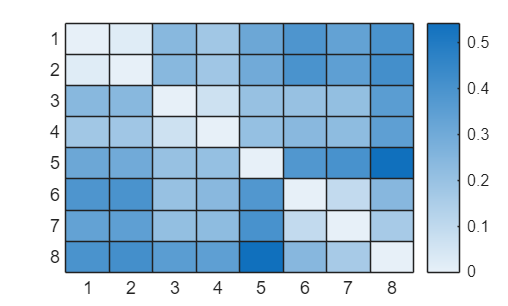

repre2 = [slopes];
dist_matri = zeros([num_files, num_files]);

for i = 1:num_files
    for j = 1:num_files
        distance = norm(repre2(i, :) - repre2(j, :));
        dist_matri(i, j) = distance;
    end
end
figure;
heatmap(dist_matri);

%select the subset of the known axons
known_axons = [1,2, 5,6, 7,8,9];
subsets = dist_matri(known_axons, known_axons);
heatmap(subsets);

groups = {[1,2], [5,6], [7,8,9]};
within_dist = [];
for i = 1:numel(groups)
    currentgroup =groups{i};
    allcomb = nchoosek(currentgroup, 2);
    within_group = zeros([height(allcomb), 1]);
    for j = 1:height(allcomb)
        within_group(j) = dist_matri(allcomb(j, 1), allcomb(j, 2));
    end
    within_dist = [within_dist; within_group];
end
mean_within_group = mean(within_dist);
fprintf('Within group distance %f\n', mean_within_group);

%out of group distance
groups = {[1,2], [5,6], [7,8,9]};
[btw_dits, btw_pairs] = getBetweenGroupDistances(dist_matri, groups);

%plot in and out dists side by side
x = ones([numel(within_dist), 1]);
figure;
hold on;
scatter(x, within_dist,15, 'red', 'filled');
x = ones([numel(btw_dits), 1])*2;
scatter(x, btw_dits, 15, 'blue', 'filled');
hold off;
%hide x tick
% Plot the mean within-group distances and between-group distances
xlabel('Group');
ylabel('Distance');
xticks([1, 2]);
xlim([0, 3]);
xticklabels({'Within Group', 'Between Group'});

%permutation test
data = [1, 2, 5, 6, 7, 8, 9];
groupSizes = [2, 2, 3];
nPerms = 100;
trial_mean = zeros([nPerms, 1]);
cutpoints = [0, cumsum(groupSizes)];

for i = 1:nPerms
    shuffled = data(randperm(length(data)));
    for g = 1:length(groupSizes)
        groups{g} = shuffled(cutpoints(g)+1 : cutpoints(g+1));
    end
    within_dist = [];
    for k = 1:numel(groupSizes)
        currentgroup = groups{k};
        allcomb = nchoosek(currentgroup, 2);
        within_group = zeros([height(allcomb), 1]);
        for j = 1:height(allcomb)
            within_group(j) = dist_matri(allcomb(j, 1), allcomb(j, 2));
        end
        within_dist = [within_dist; within_group];
    end
    trial_mean(i) = mean(within_dist);
end

%maually plot the 